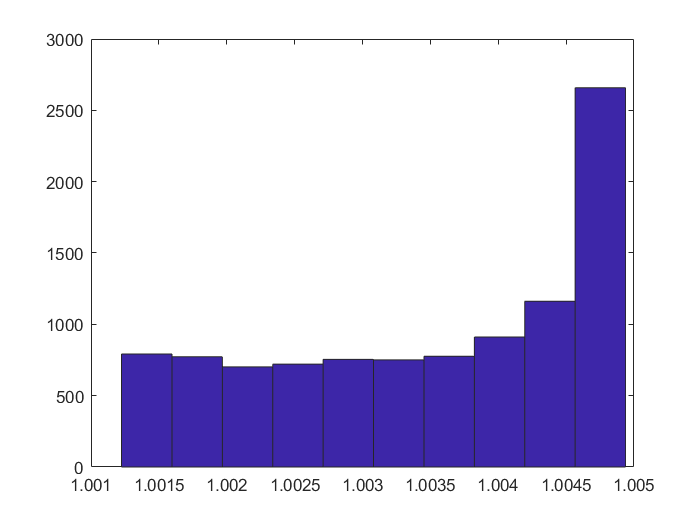

% Deterministic (non-random) parameters
V0 = 0.1; Ax = 1.0; L = 1.0; dt = 0.001;
a0Max = 60. * pi / 180.;
% 1. Generate a random sample of the input parameters
a0MC = rand(10000, 1) * a0Max;
% Array to store Monte Carlo outputs
vxMC = [];
vrMC = [];
% 2. Analyze (deterministically) each set of inputs in the sample
for i = 1:10000
    [vx, vr] = thruster(V0, a0MC(i), Ax, L, dt);
    vxMC = [vxMC; vx];
    vrMC = [vrMC; vr];
end
% 3. Estimate the desired probabilistic outputs
% histogram
figure; hist(vxMC);

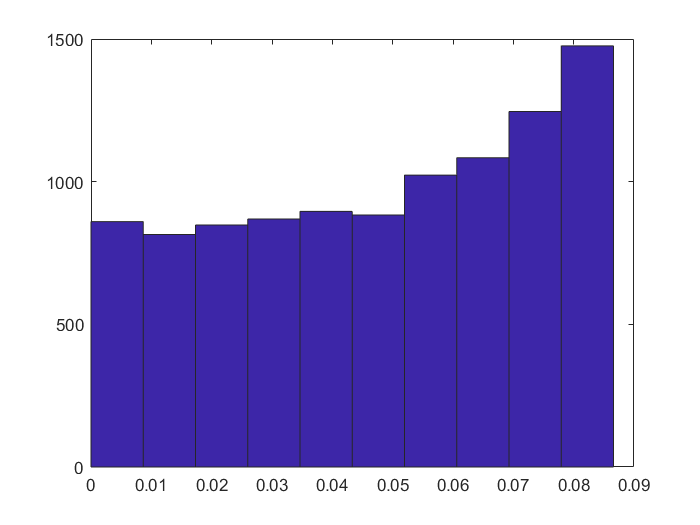

figure; hist(vrMC);

% mean
muVx = mean(vxMC)

muVx = 1.0035

muVr = mean(vrMC)

muVr = 0.0478

% standard deviation
sigmaVx = std(vxMC)

sigmaVx = 0.0012

sigmaVr = std(vrMC)

sigmaVr = 0.0256